% Author: Gerardo Parra
clear

%% parameters for running batch script
% parameters for loading data
task      = 'sl';
beapp_tag = '_seg_.1_30_200msblcorr';
file_tag  = [beapp_tag '_2023-01-23_gp'];
data_path = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );

% parameters for processing
method      = 'conds_peak';
rois        = {'Fz','T7','T8','P7P8'};
groups      = 1:3;
erps        = {'P1','N2','P2','Na','P1_N2_dist','N2_P2_dist','Na_P2_dist'};  % components to calculate/plot
exclude     = {};
r_d_avg     = true;    % for SL: average rise and decay
rm_outliers = true;    % remove outliers
conds       = [5:8];  % subset of conds to process, [] for all

% parameters for plots
norm_data   = false;
save_figs   = false;
xlims       = [1 8]; ylims = [-3 6];
cond_names  = [0:10:70 70:-10:0];
colors      = {'#4444c9','#32a852','#e69a0e'};
group_names = {'TD','ASD','SPD'};

  

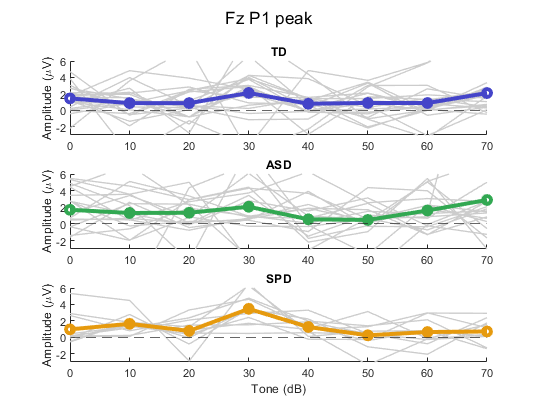

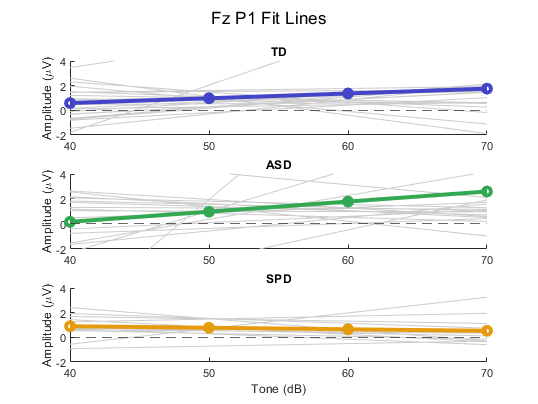

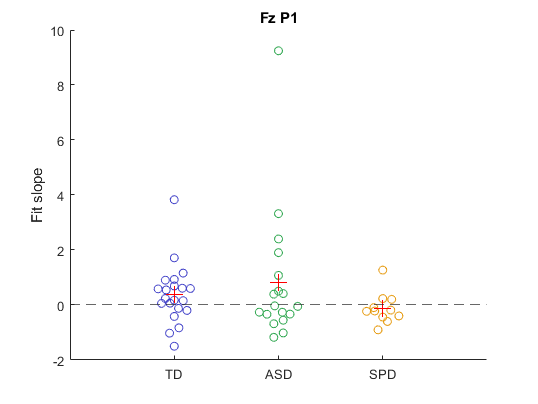

stats = struct with fields:
    p_MW_12: 0.5828
     p_t_12: 0.4780
    p_MW_23: 0.3808
     p_t_23: 0.2220

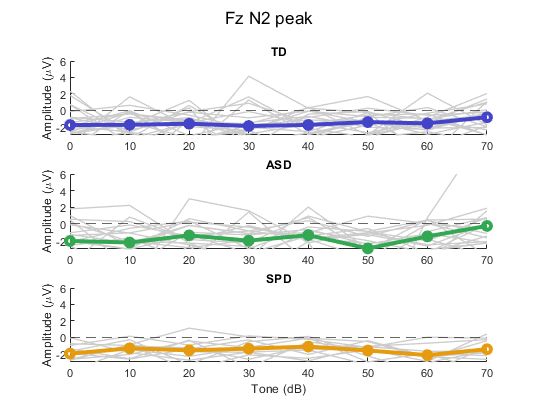

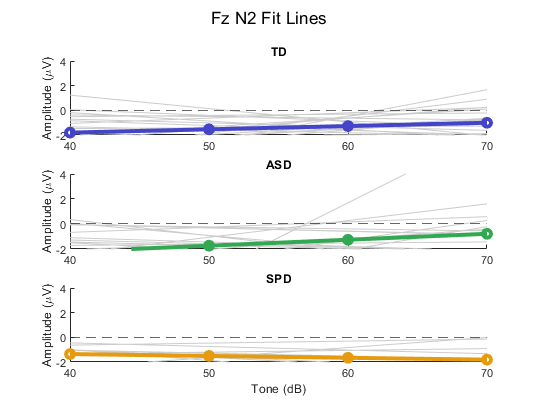

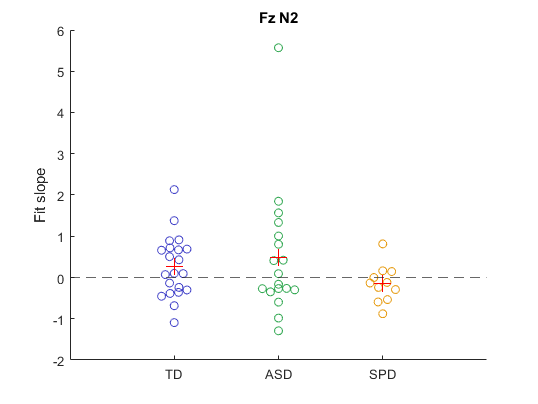

stats = struct with fields:
    p_MW_12: 0.9439
     p_t_12: 0.5829
    p_MW_23: 0.4315
     p_t_23: 0.2002

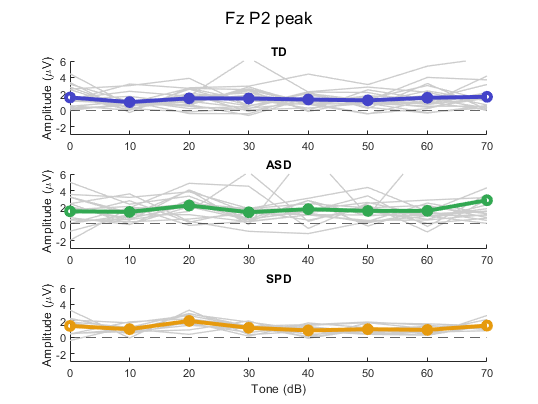

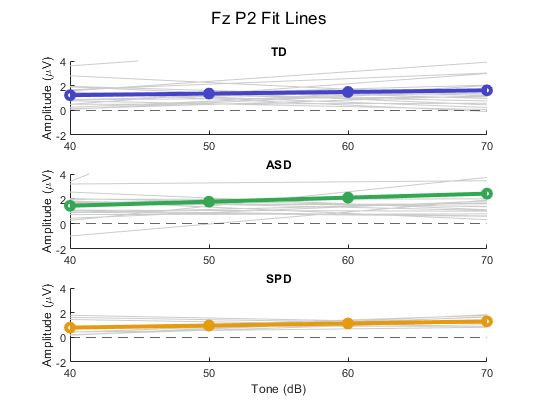

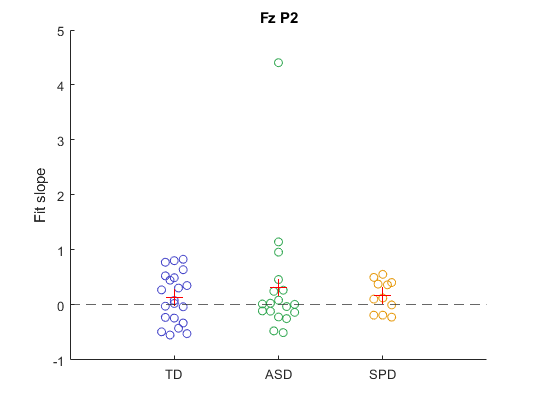

stats = struct with fields:
    p_MW_12: 0.9215
     p_t_12: 0.4710
    p_MW_23: 0.4860
     p_t_23: 0.6549

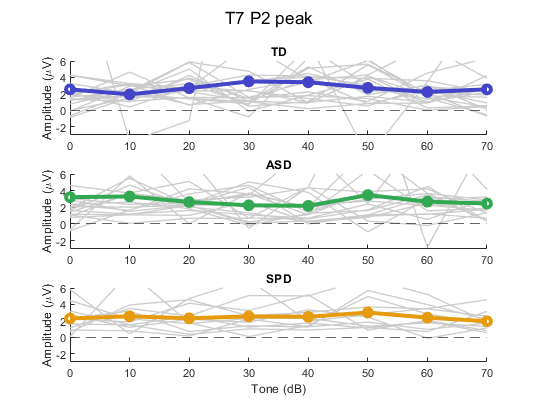

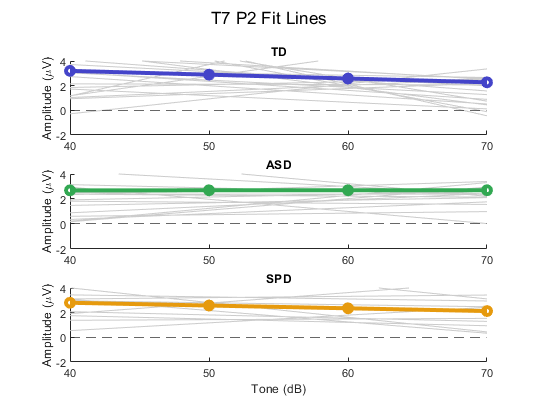

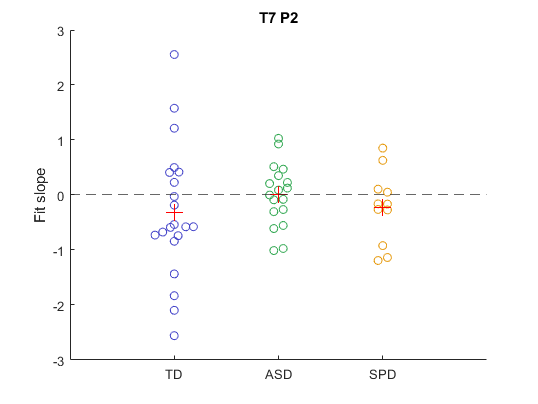

stats = struct with fields:
    p_MW_12: 0.2204
     p_t_12: 0.3193
    p_MW_23: 0.3119
     p_t_23: 0.3308

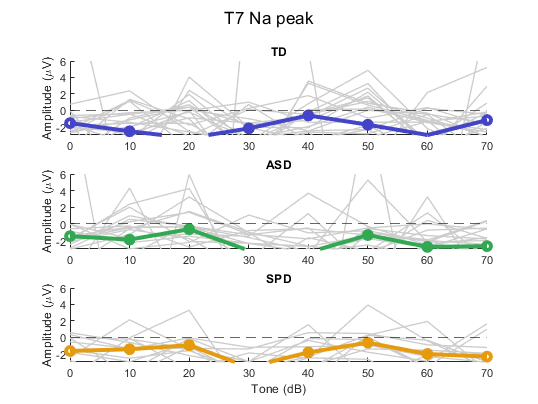

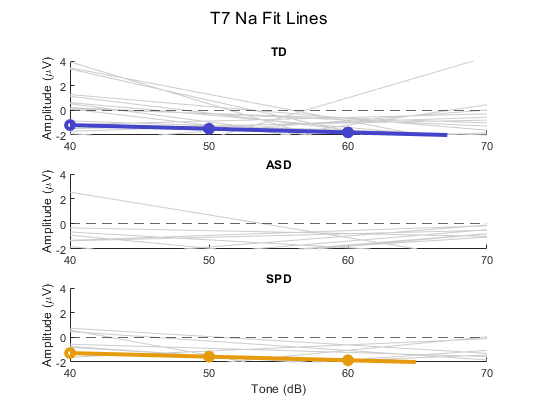

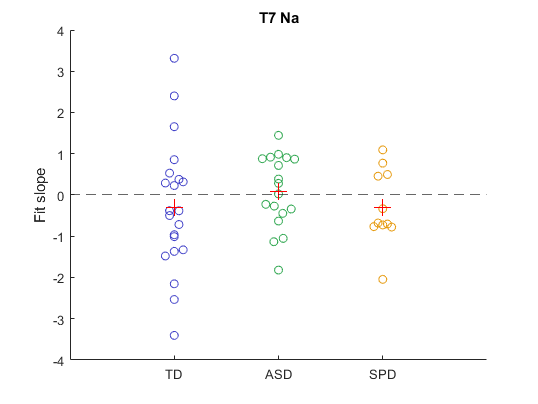

stats = struct with fields:
    p_MW_12: 0.1902
     p_t_12: 0.3732
    p_MW_23: 0.2336
     p_t_23: 0.2836

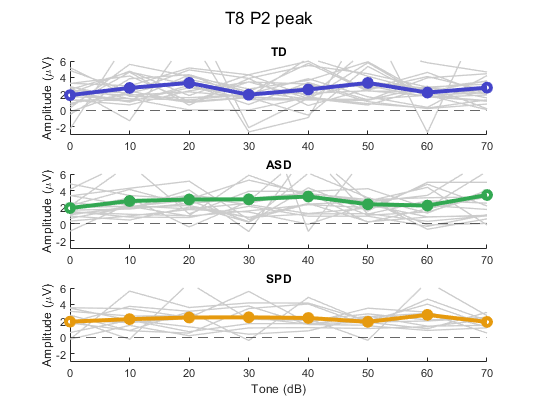

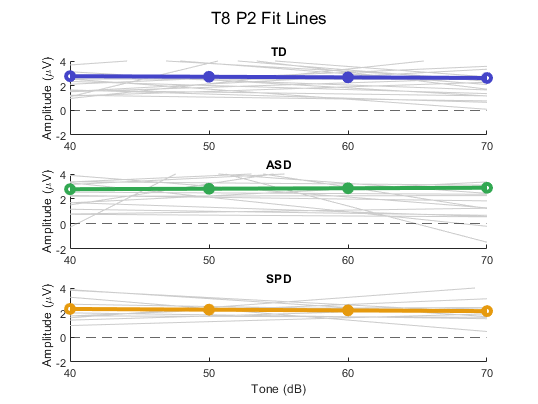

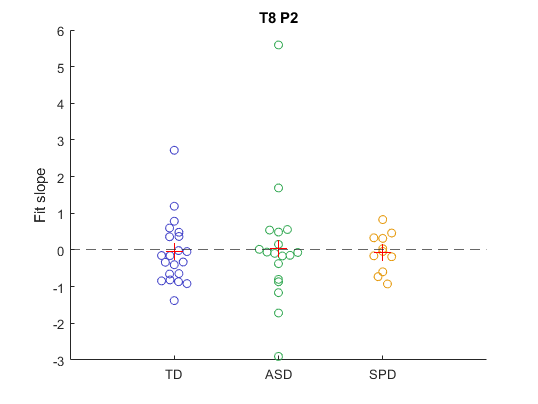

stats = struct with fields:
    p_MW_12: 0.8991
     p_t_12: 0.8380
    p_MW_23: 0.8397
     p_t_23: 0.8550

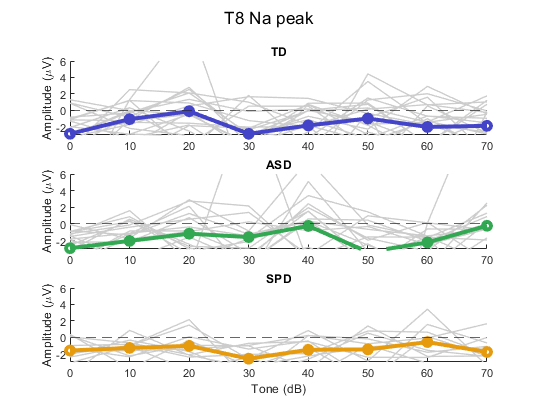

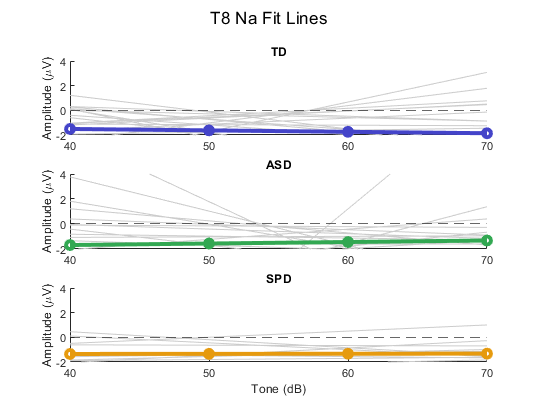

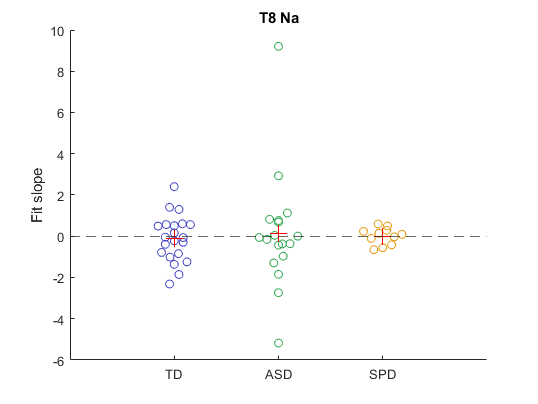

stats = struct with fields:
    p_MW_12: 0.9439
     p_t_12: 0.7270
    p_MW_23: 0.7360
     p_t_23: 0.8978

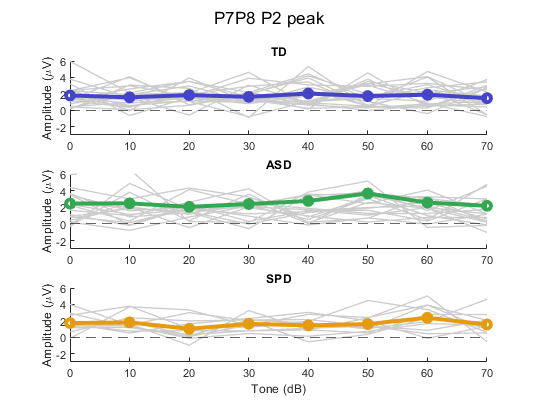

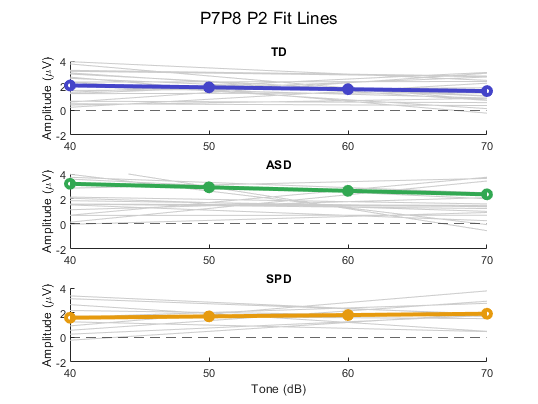

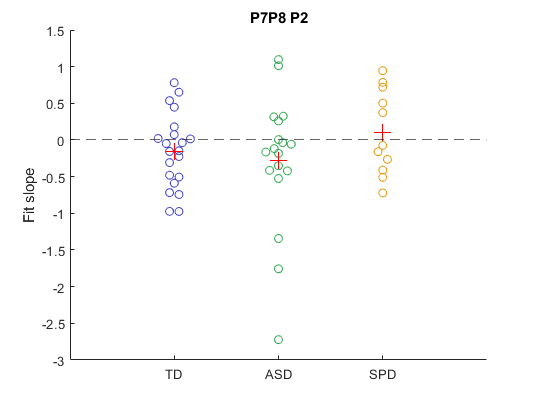

stats = struct with fields:
    p_MW_12: 0.9215
     p_t_12: 0.5793
    p_MW_23: 0.3808
     p_t_23: 0.2163

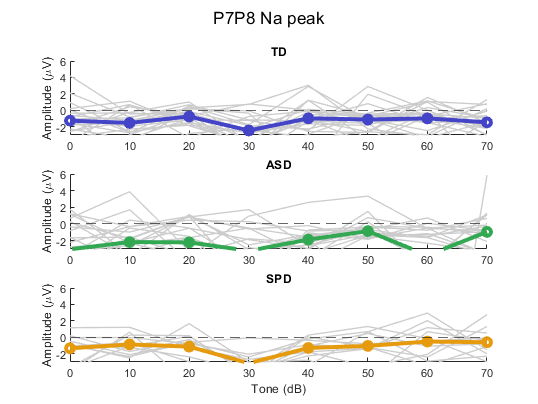

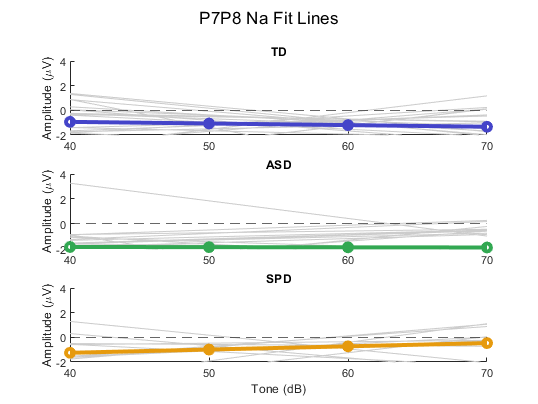

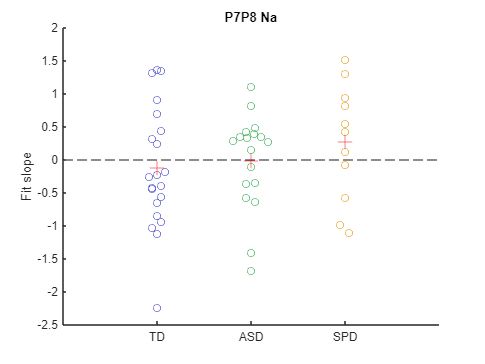

stats = struct with fields:
    p_MW_12: 0.4901
     p_t_12: 0.6630
    p_MW_23: 0.3119
     p_t_23: 0.3647

%% get batch information/data
% load erp batch
task_path = get_task_path(task);
if r_d_avg, file_tag = [file_tag '_rise-decay_avg']; end
task_path_batch = fullfile(data_path,task_path,'erp',['erp' file_tag '.mat']);
load(task_path_batch,'batch');
% add method to batch for choosing data to load
if norm_data, method = [method '_norm']; end
batch.method  = method; 
% sort batch data into tables
data = sort_data_into_group_tables_v2(batch,exclude);

%% plot data
n_grp = length(groups);
n_roi = length(rois);
n_erp = length(erps);
% iterate through rois
for i_r = 1:n_roi
    roi = rois{i_r};
    % iterate through erp components
    for i_e = 1:n_erp
        erp = erps{i_e};
        %% sort data into group cells
        % skip if ERP not in ROI
        if ~isfield(data.(roi),erp), continue; end
        erp_data = data.(roi).(erp);
        % initialize cell to store group data
        group_data = cell(n_grp,1);
        % iterate through groups
        for i_g = groups
            % get all group data
            group_all = erp_data([erp_data.group] == i_g);
            group_data{i_g} = [group_all.data];            
        end
        n_cond = size(group_data{i_g},1);

        %% plot erp data
        figure, hold on
        ax = zeros(1,n_grp);
        for i_g = groups
            ax(i_g) = subplot(n_grp,1,i_g); hold on
            % plot individual data
            plot(group_data{i_g},'Color','#ccc','LineWidth',1)
            yline(0,'--')
            % plot group mean
            plot(mean(group_data{i_g},2),'-o','Color',colors{i_g},'LineWidth',3)
            % format subplot
            title(group_names{i_g}), ylabel('Amplitude (\muV)')
            xticks(1:n_cond), xticklabels(cond_names)
        end
        % format plot
        linkaxes(ax), ylim(ylims), xlim(xlims), xlabel('Tone (dB)')
        pk_type = split(method,'_');
        plot_title = plaintext( [roi ' ' erp ' ' pk_type{2}] );
        sgtitle(plot_title)

        %% fit function to data
        figure, hold on, ax = zeros(1,n_grp);
        coeffs = cell(1,n_grp);
        n_cond = length(conds);
        for i_g = groups
            ax(i_g) = subplot(n_grp,1,i_g); hold on
            n_subj = size(group_data{i_g},2);
            coeffs{i_g} = zeros(n_subj,2);
            for i_s = 1:n_subj
                x = 1:n_cond; y = group_data{i_g}(conds,i_s);
                s_c = polyfit(x,y,1);
                plot(polyval(s_c,x),'Color','#ccc')
                coeffs{i_g}(i_s,:) = s_c;
            end
            plot(polyval(mean(coeffs{i_g},1),x),'-o','Color',colors{i_g},'LineWidth',3)
            title(group_names{i_g}), yline(0,'--'), ylabel('Amplitude (\muV)')
            xticks(1:n_cond), xticklabels(cond_names(conds))
        end
        linkaxes(ax), ylim([-5 7]), xlabel('Tone (dB)')
        sgtitle([roi ' ' erp ' Fit Lines']), ylim([-2 4])

        %% plot slopes
        figure
        slopes = cellfun(@(x) x(:,1),coeffs,'UniformOutput',false);
        plotSpread(slopes,'showMM',2,'distributionColors',colors,'distributionMarkers','o')
        yline(0,'--'), ylabel('Fit slope'), title([roi ' ' erp])
        xticks(groups), xticklabels(group_names)

        % stats
        stats.p_MW_12    = ranksum(slopes{1},slopes{2});
        [~,stats.p_t_12] = ttest2(slopes{1},slopes{2});
        stats.p_MW_23    = ranksum(slopes{2},slopes{3});
        [~,stats.p_t_23] = ttest2(slopes{2},slopes{3});

        stats
    end
end